THD_st.name='THD'; 
THD_st.lat=41.05;
THD_st.lon=-124.15;
THD_st.alt=107;
THD_st.env='coast';
THD_st.footp='RB';


THD_rd=read_betsy('thd_2002_2017',THD_st.name);

datevec(THD_rd.Time(1))

ans =         2002           4          10           0           0           0

datevec(THD_rd.Time(end))

ans =         2017           6           2           0           0           0

prctile(THD_rd.U0_S,[5 50 95])

ans =    16.1150   27.5000   38.4500

prctile(THD_rd.U1_S,[5 50 95])

ans =    16.0000   26.9000   37.4000

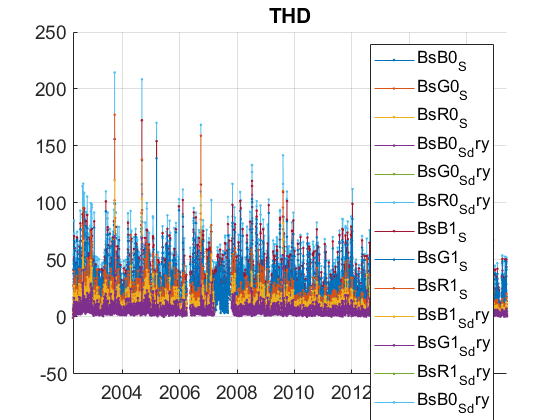

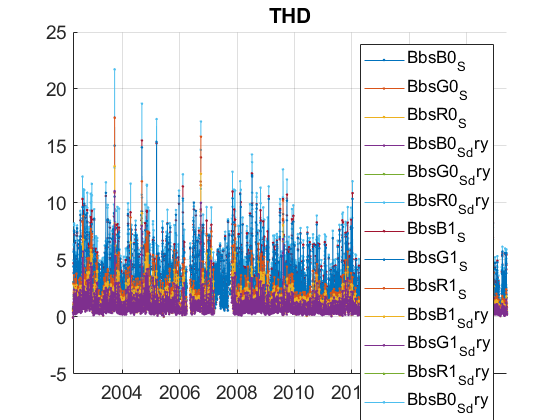

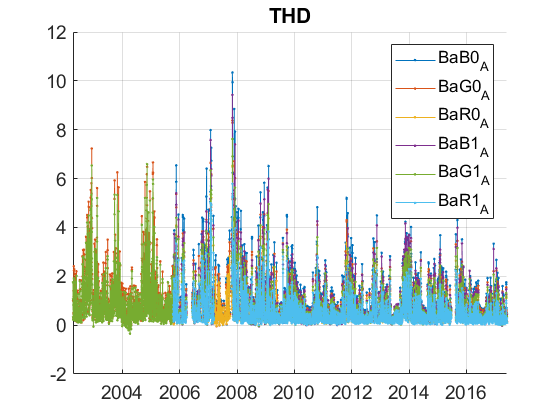

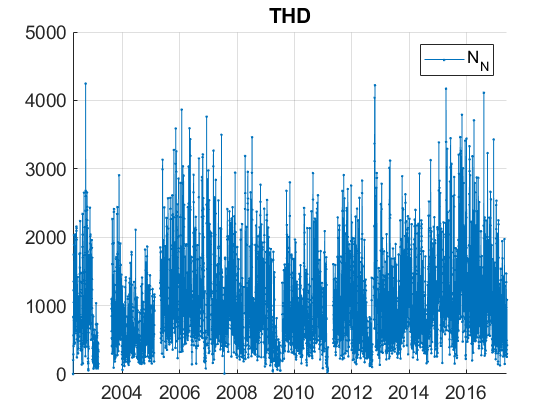

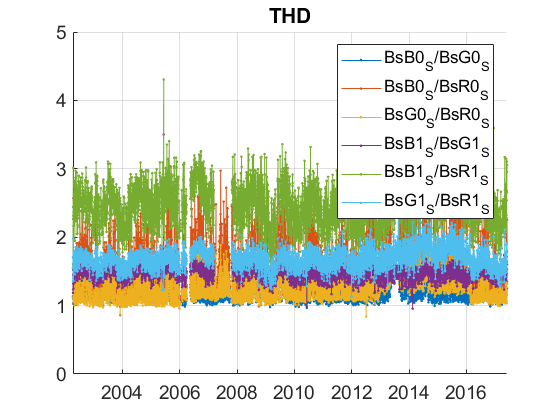

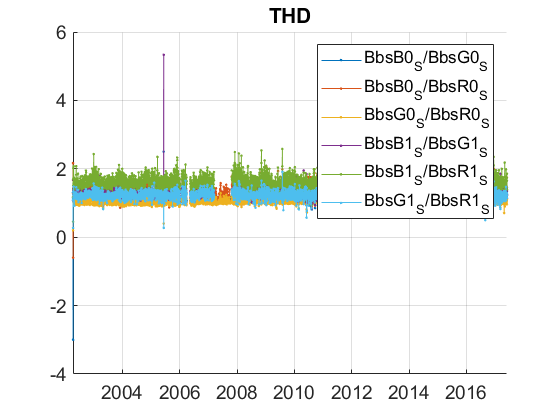

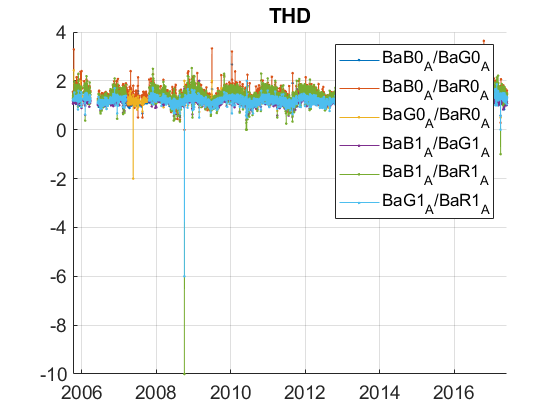

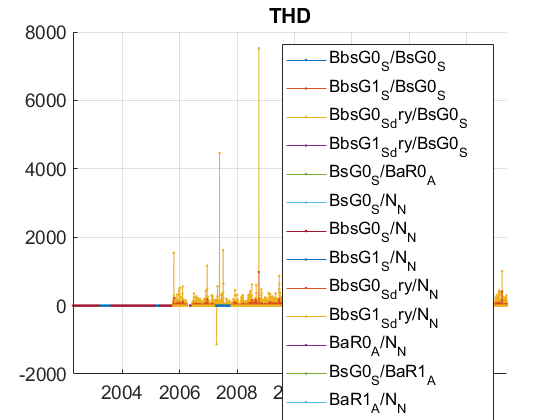

plotFigControl(THD_rd,THD_st.name);

% 2 size cut, 
% sc: ok, no clear seasonal cycle, no negatives
%abs: max in winter
%abs: change 1w to 3w end of 2005,change to CLAP in 2013 some negatives, abs maxima in winter
%abs: ratio between w: clear seasonal cycle, max in winter

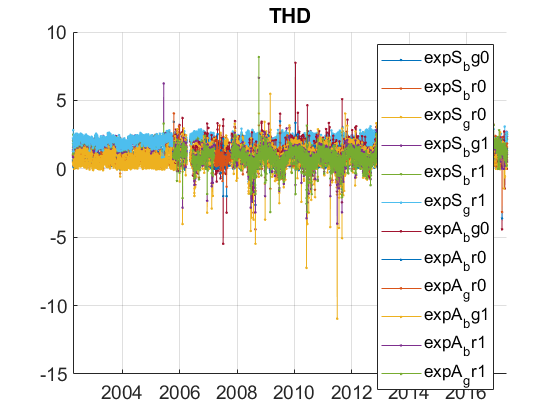

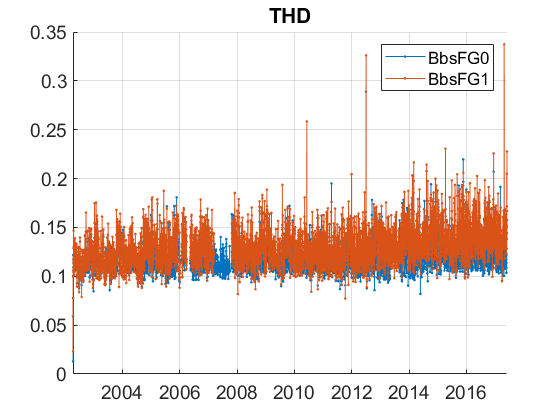

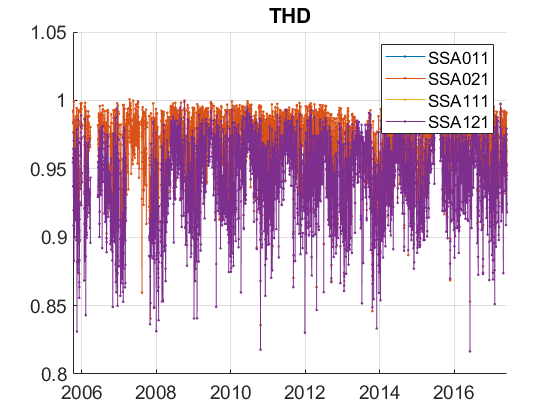

lambdaSC=[450;550;700]*ones(1,4);
lambdaAE=[467;530;660]*ones(1,4);
lambdaAE7=[370 470 520 590 660 880 950];
THD_cal=compute_exp_SSA(THD_rd,lambdaSC, lambdaAE);
plotFigControl_cal(THD_cal, THD_st.name);

THD_cal.SSA1_G=THD_rd.BsG1_S./(THD_rd.BsG1_S+THD_rd.BaG1_A);
THD_cal.SSA0_G=THD_rd.BsG0_S./(THD_rd.BsG0_S+THD_rd.BaG0_A);
hold on;
plot(THD_rd.Time,SSA0_G,'.g');
plot(THD_rd.Time,SSA1_G,'.c');

%Questions:
%problems:
%scat: ratio G/R and B/R have higher maxima from January to November 2007 and from November 2012 to March 2016. The B/G ratio is much more constant. This phenomena is also much less visible in the backscattering ratios. Can you explain these differences ?
% scattering exponent: minima problem also visible also for the BG pair. The exponent maxima also increase in July 2005: Any reason?


%abs: lower maxima values since 2009: is there any reason ?
%abs: the changes between instruments seems not to be visible in the data. Did you analyse both changes in details?
%abs: ratio between wavelength: minima clearly higher from october 2005 to March 2006 (= begin of PSAP 3w)
% abs: ratio also higher from 2013 (change from PSAP 3w to CLAP), mostly for ratio with red. Also visible in the absoprtion exponent.
% SSA:PM10 (= SSA021) maxima lower since CLAP ? also visible in green? less visible in PM1 (SSA121)? what is your opinion ?

%--> SSA should be calculated with the gree wavelength, first because it is longer (with PSAP 1w)

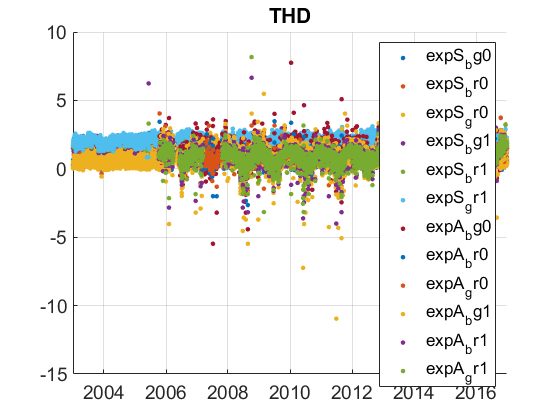

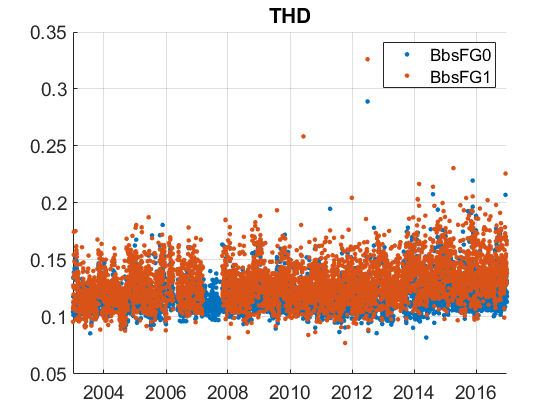

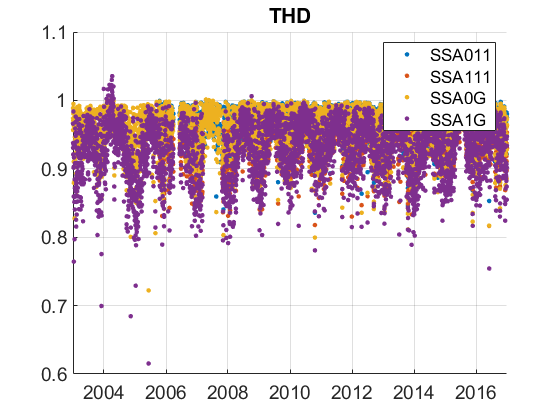

THD_tr=THD_rd;
THD_tr.y=year(THD_tr.Time);
% begin at the beginning of a year: 2003
%end: 2016
P=timerange('2003-01-01','2017-01-01');
THD_tr=THD_tr(P,:);
%take U0_S since U1_S has no data in part of 2007, but U0 has some data less in 2013
%trend in RH have to be calculated since it is lower since 2012
%few RH values > 50%, only at the beginning where scat= NaN: few difference, don't use dry
names=fieldnames(THD_tr);
c= startsWith(names,["T1";"T0";"T_";"P_";"P1_";"P0_";"N";"Uu";"U1"]) | endsWith(names,'dry') | contains(names,'Q');
N=names(c);
for i=1:length(N)
    THD_tr.(N{i})=[];
end
%take green SSA
THD_cal2=compute_exp_SSA(THD_tr,lambdaSC, lambdaAE);
% absG is longer than absR --> compute SSA with green scat and abs
THD_cal2.SSA0G=THD_tr.BsG0_S./(THD_tr.BsG0_S+THD_tr.BaG0_A);
THD_cal2.SSA1G=THD_tr.BsG1_S./(THD_tr.BsG1_S+THD_tr.BaG1_A);
plotFigControl_cal(THD_cal2,THD_st.name);

THD_tr=outerjoin(THD_tr, THD_cal2);

%compute abs and SSA trends only on G, the longest time series
%SSA from Juan 2004 to April 2004 is too high, mostly for PM1: invalidate 2004??
THD_tr.BaB0_A=[];
THD_tr.BaB1_A=[];
THD_tr.BaR0_A=[];
THD_tr.BaR1_A=[];
THD_tr.SSA011=[];
THD_tr.SSA111=[];
%compute expA exponent only on BG and only since 1.1.2006 (whole year)
Pexp=timerange('2003-01-01','2006-01-01');
THD_tr.expA_bg0(Pexp)=NaN;
THD_tr.expA_bg1(Pexp)=NaN;
THD_tr.expA_br0=[];
THD_tr.expA_br1=[];
THD_tr.expA_gr0=[];
THD_tr.expA_gr1=[];

%compute trend on G
THD_tr.BsB0_S=[];
THD_tr.BsR0_S=[];
THD_tr.BsB1_S=[];
THD_tr.BsR1_S=[];
THD_tr.BbsB0_S=[];
THD_tr.BbsR0_S=[];
THD_tr.BbsB1_S=[];
THD_tr.BbsR1_S=[];

THD_tr.expS_br0=[];
THD_tr.expS_br1=[];
THD_tr.expS_gr0=[];
THD_tr.expS_gr1=[];

THD_result= all_trend_STN(THD_tr,THD_st); 

THD_result_D=THD_result;
%expS_bg1 and idem A to remove not to plot results for PM1
THD_result_D=THD_result_D(startsWith(THD_result_D.parameter,["expS_bg1";"expS_bg1"])==0,:);